clear all
% load('NewNINeuron7.mat')
load('Neuron1.mat')
load('QsumStruct.mat')

% i=53;
n=20;
% VSpike=Neuron(i).Spike.VVVV;
% ASpike=Neuron(i).Spike.AAAA;
% MSpike=Neuron(i).Spike.MMMM;
% AVSpike=Neuron(i).Spike.AAAV;
% AMSpike=Neuron(i).Spike.AAAM;
% MASpike=Neuron(i).Spike.MMMA;
% VASpike=Neuron(i).Spike.VVVA;
% VMSpike=Neuron(i).Spike.VVVM;
% MVSpike=Neuron(i).Spike.MMMV;

VSpike=VFullbTrial;
ASpike=AFullbTrial;
MSpike=MFullbTrial;
AVSpike=AAAVFullbTrial;
AMSpike=AAAMFullbTrial;
MASpike=MMMAFullbTrial;
VASpike=VVVAFullbTrial;
VMSpike=VVVMFullbTrial;
MVSpike=MMMVFullbTrial;

[AFR] = scottmakeraster(ASpike,n);
[AVFR] = scottmakeraster(AVSpike,n);
[AMFR] = scottmakeraster(AMSpike,n);
t1=Data(AO).Stim.AudOnsetCh1(4)+499;
t2=Data(AO).Stim.AudOnsetCh1(4)+500;
mAfr=[AFR;AVFR;AMFR];
AvgAFR=[mean(mAfr(:,1:t1)) AFR(:,t2:end)];
AvgAVFR=[mean(mAfr(:,1:t1)) AVFR(:,t2:end)];
AvgAMFR=[mean(mAfr(:,1:t1)) AMFR(:,t2:end)];

[VFR] = scottmakeraster(VSpike,n);
[VAFR] = scottmakeraster(VASpike,n);
[VMFR] = scottmakeraster(VMSpike,n);
t1=Data(VO).Stim.VisOnsets1(4)+449;
t2=Data(VO).Stim.VisOnsets1(4)+450;
mVfr=[VFR;VAFR;VMFR];
AvgVFR=[mean(mVfr(:,1:t1)) VFR(:,t2:end)];
AvgVAFR=[mean(mVfr(:,1:t1)) VAFR(:,t2:end)];
AvgVMFR=[mean(mVfr(:,1:t1)) VMFR(:,t2:end)];



[MFR] = scottmakeraster(MSpike,n);
[MAFR] = scottmakeraster(MASpike,n);
[MVFR] = scottmakeraster(MVSpike,n);
t1=Data(VO).Stim.VisOnsets1(4)+449;
t2=Data(VO).Stim.VisOnsets1(4)+450;
mMfr=[MFR;MAFR;MVFR];
AvgMFR=[mean(mMfr(:,1:t1)) MFR(:,t2:end)];
AvgMAFR=[mean(mMfr(:,1:t1)) MAFR(:,t2:end)];
AvgMVFR=[mean(mMfr(:,1:t1)) MVFR(:,t2:end)];


% maketempgraphs(AFR,VFR,MFR,'MMMM')

t=[1:2500];
k=120

k = 120

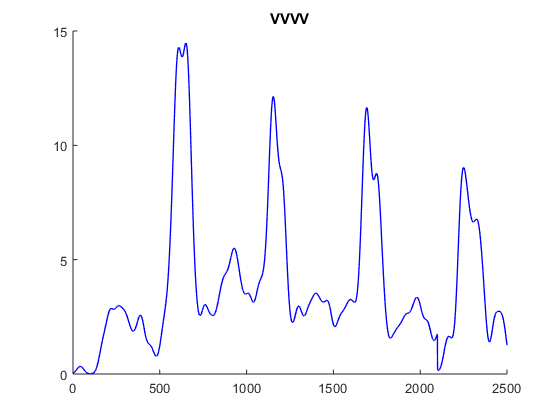

figure
plot(t,AvgVFR(1:2500),'Color','b','LineStyle','-',"LineWidth",1)
% hold on

% xlabel('Time (ms)')
% ylabel('firing rate (spk/s)')
% set(gca,'xtick',[]);
%  set(gca,'xcolor',[1 1 1])
% ylim([0 k])
% plot([500 500], ylim,'Color','k')
title('VVVV')
box off

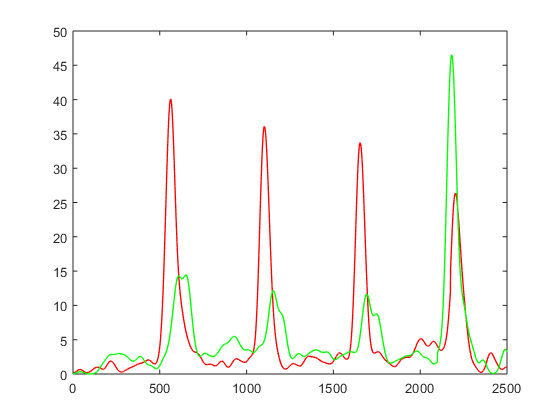

% hold off 
plot(t,AvgAFR(1:2500),'Color','r','LineStyle','-',"LineWidth",1)
hold on
plot(t,AvgVAFR(1:2500),'Color','g','LineStyle','-',"LineWidth",1)

A=mean(ASpike,1);
% figure
% plot(t,A(1:2500),'Color','g','LineStyle','-',"LineWidth",1)
% 
% % ylim([0 k])
% % set(gca,'xtick',[]);
% %  set(gca,'xcolor',[1 1 1])
% title('AAAA')
% box off
% hold off



% [VRaster]=oldvistog(500,Data(VO).Data.Spikes,Data(VO).Stim.VisOnsets1,Data(VO).Stim.VisOffsets1,Data(VO).Stim.delta1,'Visual','b') ;
% [ARaster]=oldvistog(500,Data(AO).Data.Spikes,Data(AO).Stim.AudOnsetCh1,Data(AO).Stim.AudOffsetCh1,Data(VO).Stim.delta1,'Auditory','r');
% 
% [Raster,VOnsets,VOffsets]=oldmultisense(Data,VVVA,'VVVA',Delta)


% [ASDR,ASpikesByTrial] = StimDrivResp(ABLS1,AS1ON,AS1OFF);
% [VSDR,VSpikesByTrial] = StimDrivResp(VBLS1,VS1ON,VS1OFF);
% 
% [MSDR,MSpikesByTrial] = StimDrivResp(MBLS1,MS1ON,MS1OFF);

%  x=MSpikesByTrial;
% if ASDR>VSDR
%     y=ASpikesByTrial;
%     BU=ASDR;
% else y=VSpikesByTrial;
%     BU=VSDR;
% end
% 
% MSI=((MSDR-BU)/BU)*100;
% [hMU,pMU]=ttest(x,y);
% 
% 
% ASD=std(A1SpikesByTrial);
% ASDerr=ASD/sqrt(18);
% 
% VSD=std(V1SpikesByTrial);
% VSDerr=VSD/sqrt(18);
% 
% MSD=std(M1SpikesByTrial);
% MSDerr=MSD/sqrt(18);
% 
% varserr=[ASDerr VSDerr MSDerr];
% 
% Names={'Auditory' 'Visual' 'Multisensory' 'MSI'};
% vars=[ASDR VSDR MSDR];
% figure
% bar(1,vars(1),'FaceColor','r')
% hold on
% bar(2,vars(2),'FaceColor','b')
% bar(3,vars(3),'FaceColor','m')
% errorbar(vars,varserr,'LineStyle','none','Color',[0 0 0]);
% 
% if MSI<0
%     msilim=[round(MSI-10) round(vars(3)+75)];
%     sdlim=msilim;
% else
%     msilim=[0 round(MSI+10)];
%     sdlim=[0 round(vars(3)+15)];
% end
% 
% set(gca, 'XTick', [1 2 3 4]);
% set(gca,'Xticklabel',Names);
% xlabel('Stimulus');
% ylabel('Stimulus Driven Response (Spikes Per Trial)');
% title('Multisensory Enhancement');
% box off;
% ylim(sdlim)
% 
% dim=[.2 .4 .5 .5];
% str={'Auditory = ',num2str(ASDR),'Visual = ',num2str(VSDR), 'Multisensory = ',num2str(MSDR),'pValue = ',num2str(pMU)};
% 
% annotation('textbox',dim,'String',str,'FitBoxToText','on');
% hold off
% 
% 
% yyaxis right
% 
% 
% bar(4,MSI,'FaceColor',[0.5 0.5 0.5])
% ylabel('%Me');
% ylim(msilim);

% maketempgraphs(AFR,VFR,AVFR,'AAAV')
% 
% maketempgraphs(AFR,VFR,AMFR,'AAAM')
% 
% maketempgraphs(AFR,VFR,MAFR,'MMMA')
% 
% maketempgraphs(AFR,VFR,VAFR,'VVVA')
% 
% maketempgraphs(AFR,VFR,VMFR,'VVVM')
% 
% maketempgraphs(AFR,VFR,MVFR,'MMMV')

